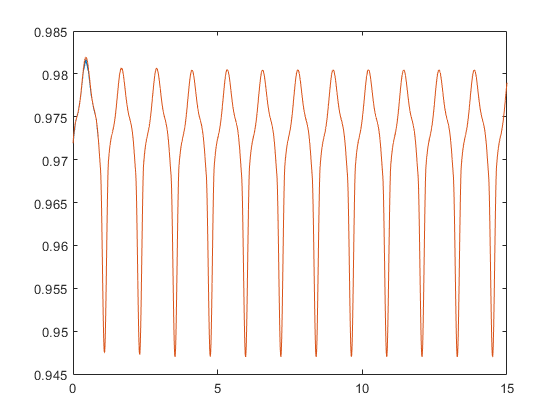

% SLIP-SL constant params
m_M = slipslParams(1);
m_swLeg = slipslParams(2);
m_swFoot = slipslParams(3);
L_thigh = slipslParams(4);
I_swLeg = slipslParams(5);
I_swFoot = slipslParams(6);
gravi = slipslParams(7);

% SLIP-SL collocation parameters
k0_ss = slipslParams(8);
L0_ss = slipslParams(9);
k_swFoot = slipslParams(10);
k_swLeg = slipslParams(11);
theta0 = slipslParams(12);
r0 = slipslParams(13);
foot = slipslParams(14);
footPlus = slipslParams(15);

y_CoM_ss = (m_swFoot*(dc.simout_ss(2,:) + sin(dc.simout_ss(3,:)).*(L_thigh + dc.simout_ss(4,:))) + m_swLeg*(dc.simout_ss(2,:) + (L_thigh*sin(dc.simout_ss(3,:)))/2) + m_M*dc.simout_ss(2,:))/(m_M + m_swLeg + m_swFoot);
dy_CoM_ss = dc.simout_ss(6,:) + (dc.simout_ss(7,:).*(m_swFoot.*cos(dc.simout_ss(3,:)).*(L_thigh + dc.simout_ss(4,:)) + (L_thigh*m_swLeg*cos(dc.simout_ss(3,:)))/2))/(m_M + m_swLeg + m_swFoot) + (dc.simout_ss(8,:).*m_swFoot.*sin(dc.simout_ss(3,:)))/(m_M + m_swLeg + m_swFoot);

figure()
plot(dc.time_ss, y_CoM_ss)
hold on
plot(time, CoM_acc(:,2))

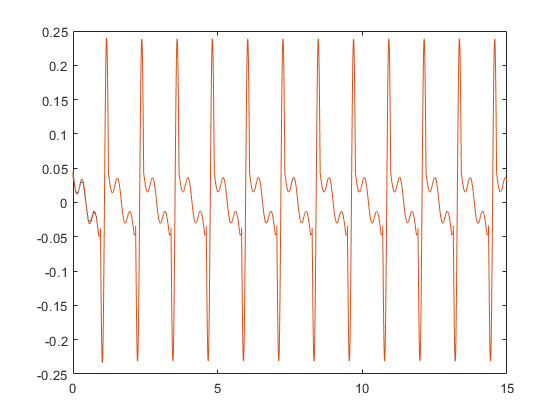


figure()
plot(dc.time_ss, dy_CoM_ss)
hold on
plot(time, CoM_acc(:,4))

## Variable Stiffness Inputs

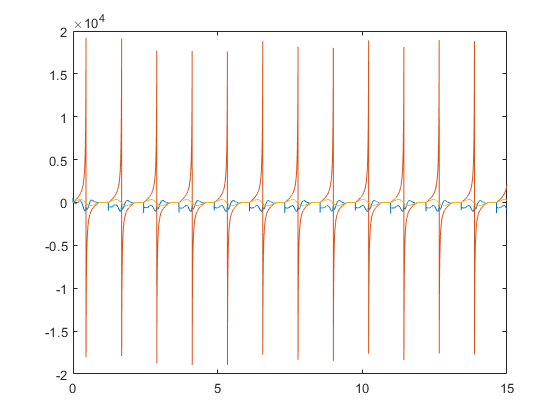

figure()

plot(time, input_varStiff(:,1:3))

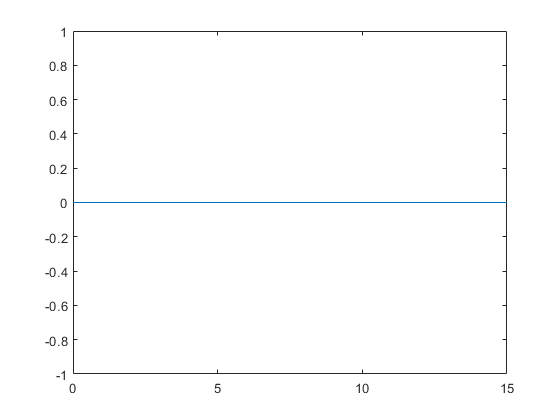


figure()
plot(time, det_A_ds)

## Inputs

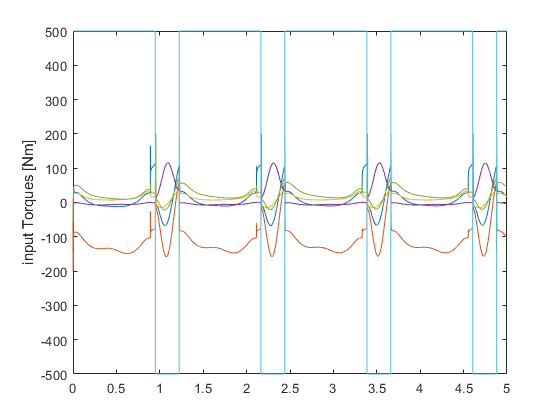

figure()
plot(time, inputTorque)
hold on
plot(time, flag(:,1)*500)
xlim([0,5])
ylabel('input Torques [Nm]')

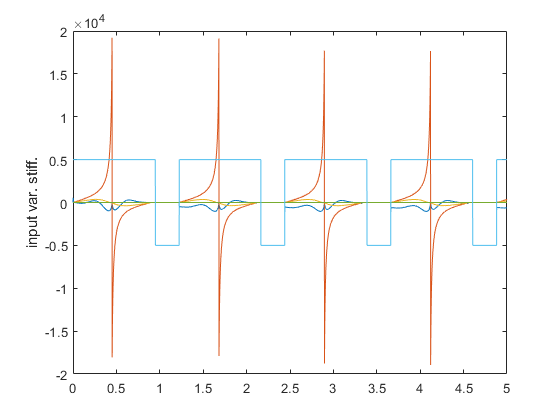


figure()
plot(time, input_varStiff)
hold on
plot(time, flag(:,1)*5000)
xlim([0,5])
ylabel('input var. stiff.')